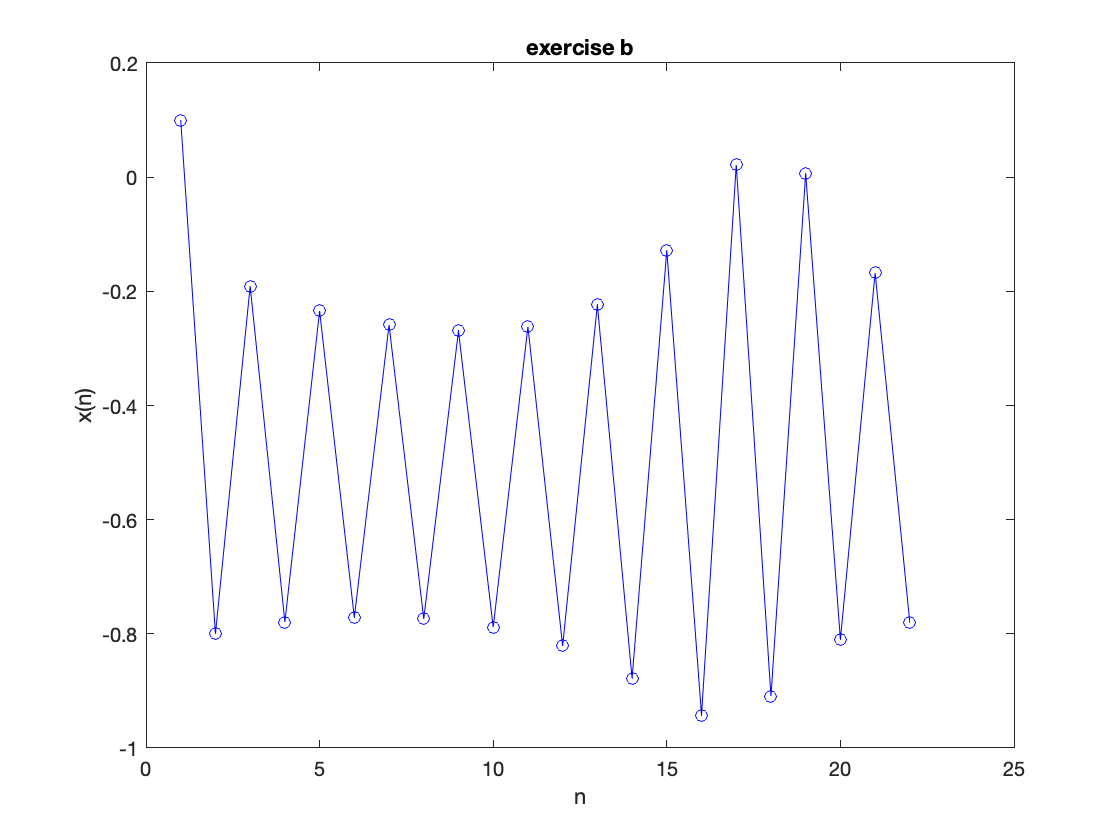

%part a
c = -0.8;
d = 0.156;
nMax = 22;

x = zeros(1,nMax);
y = zeros(1,nMax);

x(1) = 0.1;
y(1) = 0.1;
N = 1:nMax;
for n=2:nMax
    x(n) = x(n-1)^2 - y(n-1)^2 + c;
    y(n) = 2*x(n-1)*y(n-1) + d;
end

%part b
figure;
plot(N, x,'-ob'); 
ylabel('x(n)')
xlabel('n')
title('exercise b')

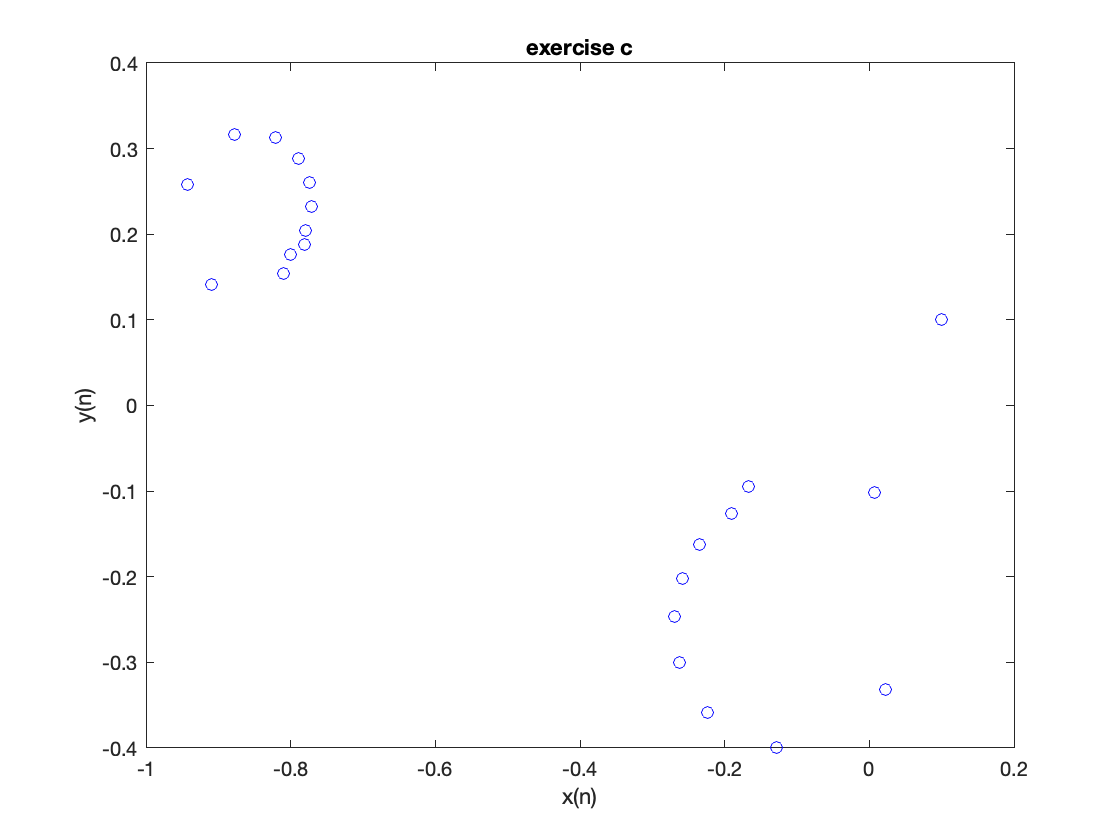


%part c
plot(x,y,'ob')
xlabel('x(n)')
ylabel('y(n)')
title('exercise c')


% part d
% In general, you can generate N random numbers 
% in the interval [a,b] with the formula r = a + (b-a).*rand(N,1);
a = -2;
b = 2;
N = 10e5;
r = a + (b-a).*rand(N,1);

% part e,f
XStart = a + (b-a).*rand(N,1);
YStart = a + (b-a).*rand(N,1);

plot(XStart,YStart,'ob');
title('exercise e')

%part g
figure;
hold on
for i=1:N
    x(1) = XStart(i);
    y(1) = YStart(i);
    for n=2:nMax
        x(n) = x(n-1)^2 - y(n-1)^2 + c;
        y(n) = 2*x(n-1)*y(n-1) + d;
    end
    if x(22) > 2 || x(22) < -2 || y(22) > 2 || x(22) < -2
        plot(x(1),y(1),'ob')
    else
        plot(x(1), y(1), 'or')
    end
end

hold off


